clear
clc
close all
% Hello, this script calculates a DMA beampattern. 
% Only works for distinct nulls. Q has other equation for null multiplicity

% To-do:
% Calculate WNG
% Overlay multiple frequencies
% Pretty up the plot

% Order of ideal function
N = 10

N = 10


% Number of microphones M > N 
M = N +1

M = 11

 
% Steering of main lobe
steerAng =146.01

steerAng = 146.0100

xs = cosd(steerAng);

% Signal frequency (Hz)
f = 1e3;                        

% Microphone spacing (m)
d = 0.01;                       

% Speed of sound (m/s)
c = 343;                                       

% Temporary null vector dim = N
nullAngles = [flip((steerAng-180/N:-180/N:0)) (steerAng+180/N:180/N:180)]' 

nullAngles =     2.0100
   20.0100
   38.0100
   56.0100
   74.0100
   92.0100
  110.0100
  128.0100
  164.0100



% Concat with steering angle
x = [xs; cosd(nullAngles)]

x =    -0.8291
    0.9994
    0.9396
    0.7879
    0.5590
    0.2755
   -0.0351
   -0.3422
   -0.6158
   -0.9613



% Set up linear system of equations
epsi = diag(0:N);
Q = cat(1, [(x(1).^(0:N)); (x(1).^(0:N)*epsi)], x(2:end).^(0:N))

Q =     1.0000   -0.8291    0.6875   -0.5700    0.4726   -0.3919    0.3249   -0.2694    0.2234   -0.1852    0.1536
         0   -0.8291    1.3749   -1.7100    1.8904   -1.9593    1.9494   -1.8857    1.7869   -1.6668    1.5355
    1.0000    0.9994    0.9988    0.9982    0.9975    0.9969    0.9963    0.9957    0.9951    0.9945    0.9939
    1.0000    0.9396    0.8829    0.8296    0.7795    0.7325    0.6883    0.6467    0.6077    0.5710    0.5365
    1.0000    0.7879    0.6208    0.4891    0.3854    0.3036    0.2392    0.1885    0.1485    0.1170    0.0922
    1.0000    0.5590    0.3125    0.1747    0.0977    0.0546    0.0305    0.0171    0.0095    0.0053    0.0030
    1.0000    0.2755    0.0759    0.0209    0.0058    0.0016    0.0004    0.0001    0.0000    0.0000    0.0000
    1.0000   -0.0351    0.0012   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000   -0.3422    0.1171   -0.0401    0.0137   -0.0047    0.0016   -0.0005    0.0002   -0.0001    0.00


% Inverse with constraint function
a = Q\eye(length(Q),1)          

a =    -0.0384
   -1.0073
    3.0023
   14.3734
  -30.9828
  -50.5589
   98.0524
   59.7472
 -113.6515
  -22.2918


xN = - a(end-1)/a(end) - sum(x(2:end))

xN = -1.0929


% Determined null vector
x = [x; xN]                     

x =    -0.8291
    0.9994
    0.9396
    0.7879
    0.5590
    0.2755
   -0.0351
   -0.3422
   -0.6158
   -0.9613



% Phase vector of microphone array
D = exp((-1i*2*pi*f*d*(0:M-1).*x)/c)

D =    1.0000 + 0.0000i   0.9885 + 0.1513i   0.9542 + 0.2991i   0.8980 + 0.4400i   0.8211 + 0.5708i   0.7252 + 0.6885i   0.6127 + 0.7903i   0.4861 + 0.8739i   0.3483 + 0.9374i   0.2024 + 0.9793i   0.0519 + 0.9987i
   1.0000 + 0.0000i   0.9833 - 0.1820i   0.9337 - 0.3580i   0.8529 - 0.5220i   0.7437 - 0.6686i   0.6095 - 0.7928i   0.4550 - 0.8905i   0.2853 - 0.9584i   0.1060 - 0.9944i  -0.0768 - 0.9970i  -0.2570 - 0.9664i
   1.0000 + 0.0000i   0.9852 - 0.1713i   0.9413 - 0.3375i   0.8696 - 0.4937i   0.7722 - 0.6354i   0.6520 - 0.7583i   0.5125 - 0.8587i   0.3578 - 0.9338i   0.1926 - 0.9813i   0.0217 - 0.9998i  -0.1499 - 0.9887i
   1.0000 + 0.0000i   0.9896 - 0.1438i   0.9586 - 0.2847i   0.9077 - 0.4196i   0.8379 - 0.5458i   0.7507 - 0.6606i   0.6479 - 0.7617i   0.5316 - 0.8470i   0.4042 - 0.9147i   0.2685 - 0.9633i   0.1271 - 0.9919i
   1.0000 + 0.0000i   0.9948 - 0.1022i   0.9791 - 0.2034i   0.9532 - 0.3024i   0.9173 - 0.3983i   0.8717 - 0.4900i   0.8171 - 0.5765i   0.7539 - 0.6570i   0


% Filter weights
h = D\eye(N+1,1)

h = 1.0e+11 *

  -0.0072 + 0.0075i
   0.0719 - 0.0736i
  -0.3243 + 0.3256i
   0.8685 - 0.8557i
  -1.5291 + 1.4787i
   1.8495 - 1.7554i
  -1.5565 + 1.4498i
   0.8999 - 0.8226i
  -0.3421 + 0.3069i
   0.0772 - 0.0680i



% Generate input
angRes = 360;
thetas = linspace(0,2*pi,angRes);
Y = exp((-1i*2*pi*f*d*(0:M-1).*cos(thetas(:)))/c)'

Y =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   0.9833 + 0.1822i   0.9833 + 0.1821i   0.98


% Output of beamformer
output = h'*Y

output =    0.0000 + 0.0010i   0.0000 + 0.0008i   0.0001 + 0.0001i   0.0003 - 0.0012i   0.0004 - 0.0028i   0.0006 - 0.0047i   0.0008 - 0.0067i   0.0010 - 0.0089i   0.0011 - 0.0111i   0.0013 - 0.0131i   0.0014 - 0.0148i   0.0015 - 0.0160i   0.0015 - 0.0170i   0.0015 - 0.0171i   0.0014 - 0.0168i   0.0012 - 0.0155i   0.0010 - 0.0136i   0.0007 - 0.0112i   0.0005 - 0.0079i   0.0002 - 0.0040i  -0.0000 + 0.0002i  -0.0002 + 0.0049i  -0.0004 + 0.0097i  -0.0005 + 0.0145i  -0.0005 + 0.0192i  -0.0005 + 0.0237i  -0.0003 + 0.0275i  -0.0002 + 0.0307i   0.0001 + 0.0330i   0.0005 + 0.0345i   0.0006 + 0.0349i   0.0009 + 0.0342i   0.0011 + 0.0322i   0.0013 + 0.0291i   0.0014 + 0.0250i   0.0012 + 0.0197i   0.0010 + 0.0136i   0.0006 + 0.0067i  -0.0001 - 0.0007i  -0.0008 - 0.0084i  -0.0018 - 0.0160i  -0.0029 - 0.0237i  -0.0040 - 0.0308i  -0.0053 - 0.0373i  -0.0066 - 0.0428i  -0.0078 - 0.0471i  -0.0089 - 0.0501i  -0.0098 - 0.0516i  -0.0105 - 0.0515i  -0.0107 - 0.0498i


bp = sqrt(power(real(output),2)+power(imag(output),2))

bp =     0.0010    0.0008    0.0002    0.0012    0.0028    0.0047    0.0068    0.0090    0.0112    0.0132    0.0149    0.0161    0.0170    0.0172    0.0168    0.0155    0.0137    0.0112    0.0079    0.0040    0.0002    0.0049    0.0097    0.0145    0.0192    0.0237    0.0275    0.0307    0.0330    0.0345    0.0349    0.0342    0.0322    0.0291    0.0250    0.0197    0.0136    0.0068    0.0007    0.0084    0.0161    0.0239    0.0311    0.0376    0.0433    0.0477    0.0509    0.0525    0.0525    0.0509


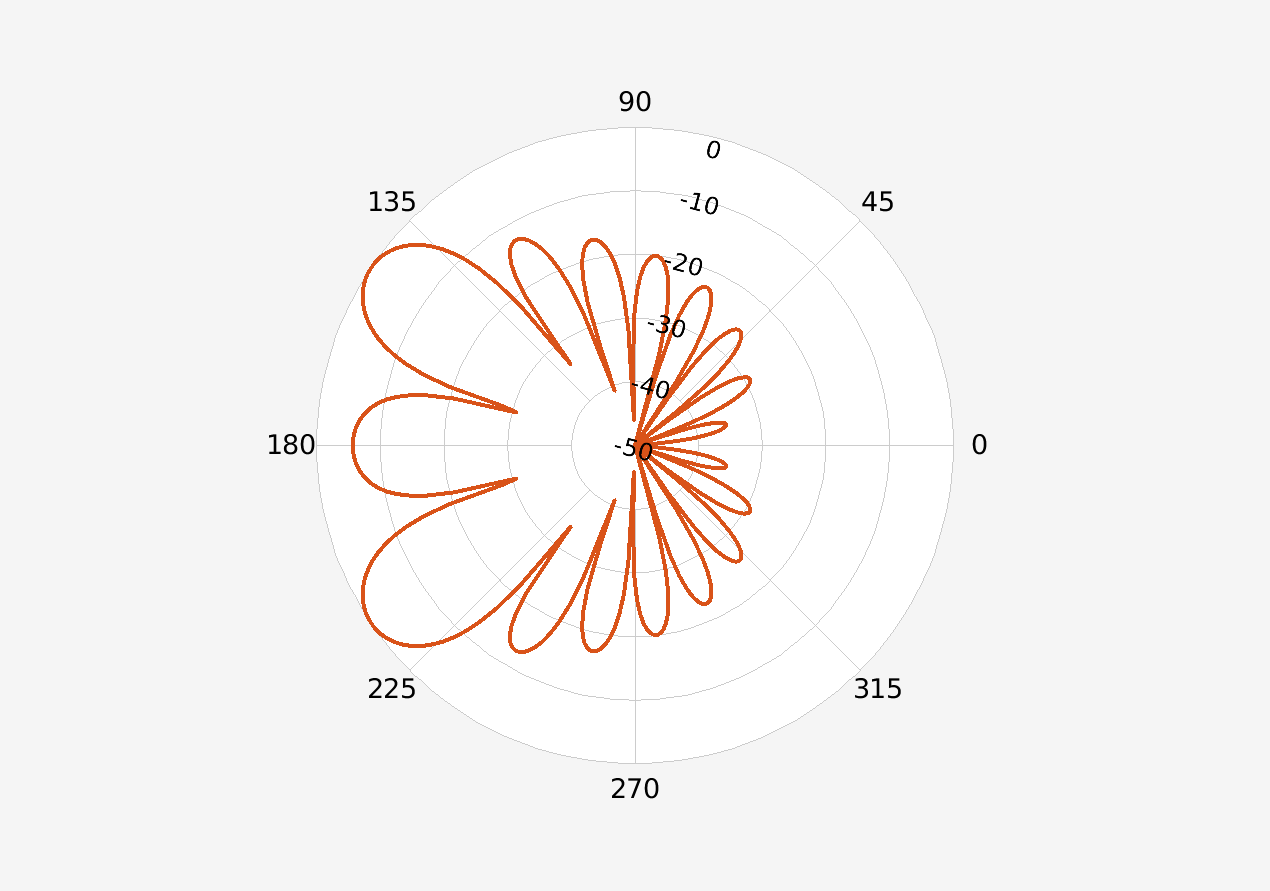


%figure()                       % For export
polarpattern(thetas*180/pi,20*log10(bp)', 'AngleResolution', 45, 'LineWidth', ...
    3, 'MagnitudeLim', [-50 0], 'ColorOrderIndex', 2)


[~, maxAng] = max(bp);
[~, minAng] = min(bp);
fprintf('Maximum: %d°\n', maxAng*360/angRes)

Maximum: 147°


fprintf('Minimum: %d°\n', minAng*360/angRes)

Minimum: 3°


%fprintf('Zeros: %i°\n', acosd(x(2:end-1)))
